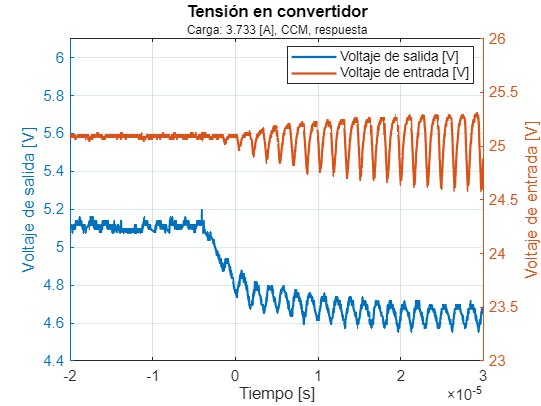

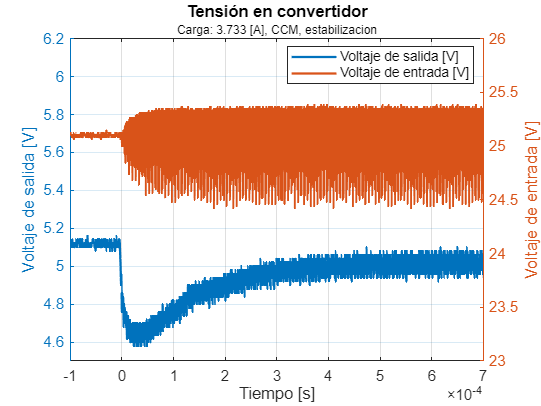

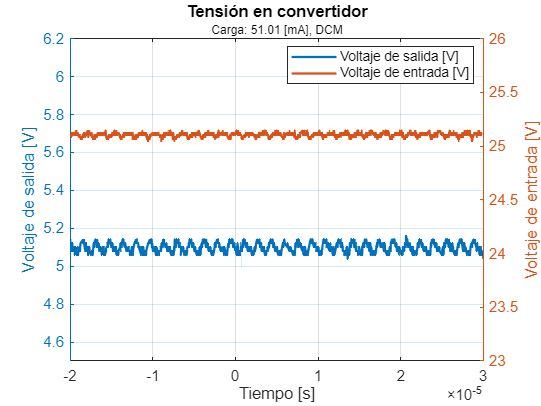

%Inputs
data = ["scope_29.csv", "scope_24.csv", "scope_38.csv"];
labels1 = {"Tiempo [s]", "Voltaje de salida [V]", "Voltaje de entrada [V]", "Tensión en convertidor", "Carga: 3.733 [A], CCM, respuesta"};
labels2 = {"Tiempo [s]", "Voltaje de salida [V]", "Voltaje de entrada [V]", "Tensión en convertidor", "Carga: 3.733 [A], CCM, estabilizacion"};
labels3 = {"Tiempo [s]", "Voltaje de salida [V]", "Voltaje de entrada [V]", "Tensión en convertidor", "Carga: 51.01 [mA], DCM"};
labels = {labels1, labels2, labels3};


limits1 = [-2e-5,3e-5 , 4.4,6.1 , 23,26]; %NaN por axis for auto 
limits2 = [-1e-4,7e-4 , 4.5,6.2 , 23,26]; %NaN por axis for auto 
limits3 = [NaN,NaN , 4.5,6.2 , 23,26]; %NaN por axis for auto 
limits = {limits1, limits2, limits3};

outputName = ["buck_ccm_rpta.png", "buck_ccm_2ss.png", "buck_dcm.png"];

%Fun Fcall
for i = 1:1:3
    plot_scope_data(data(i), labels{i}, limits{i}, outputName(i));
end